# Overall bar chart for plastic and non-plastic vs control, edge, and sample

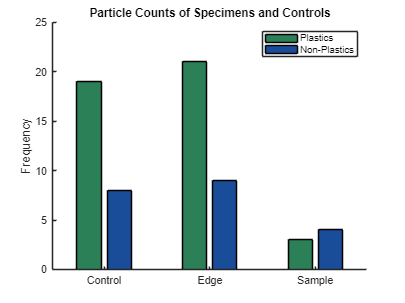

data = [19 8 1 7 0; 21 9 6 2 1; 3 4 3 1 0];
categories = {'Plastics', 'Non-Plastics'};
plastic_data = data(:, 1:2);

b = bar(plastic_data, 'FaceColor', 'flat');
xticklabels({'Control', 'Edge', 'Sample'});
title('Particle Counts of Specimens and Controls');
ylabel('Frequency');
legend(categories, 'Location', 'northeast');
box off;

% sets the color for each pair in the respective groups
colors = [0.17, 0.5, 0.34; 0.1, 0.3, 0.6];
for k = 1:numel(b)
    b(k).CData = repmat(colors(k,:), size(plastic_data,1), 1); 
end

## Overall bar chart for plastic vs non-plastic (edge and sample combined)

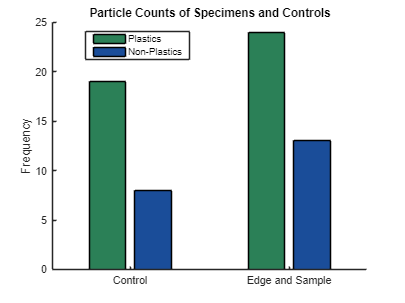


data_combined = [19 8 1 7 0; 24 13 9 3 1];
categories = {'Plastics', 'Non-Plastics'};
c_plastic_data = data_combined(:, 1:2);

b = bar(c_plastic_data, 'FaceColor', 'flat');
xticklabels({'Control', 'Edge and Sample'});
title('Particle Counts of Specimens and Controls');
ylabel('Frequency');
legend(categories, 'Location', "none", "Position", [0.2243 0.8073 0.2311, 0.0840]);
box off;

% sets the color for each pair in the respective groups
colors = [0.17, 0.5, 0.34; 0.1, 0.3, 0.6];
for k = 1:numel(b)
    b(k).CData = repmat(colors(k,:), size(c_plastic_data,1), 1); 
end

## Same as above but combines them into one figure

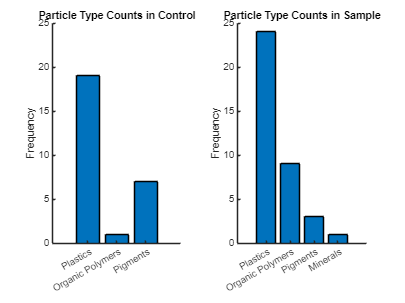


% add color*
cat_data = data_combined(:, [1,3,4,5]);
tiledlayout(1,2);
y_lim = [0, max(cat_data(:)) + 1];

nexttile(1)
bar(cat_data(1,[1 2 3])); % excludes mineral category
xticklabels({'Plastics','Organic Polymers','Pigments'});
title('Particle Type Counts in Control');
ylabel('Frequency');
ylim(y_lim)
box off;

nexttile(2)
bar(cat_data(2,:)); % excludes mineral category
xticklabels({'Plastics','Organic Polymers','Pigments', 'Minerals'});
title('Particle Type Counts in Sample');
ylabel('Frequency');
ylim(y_lim)
box off;

## Specific particle type bar charts for each area

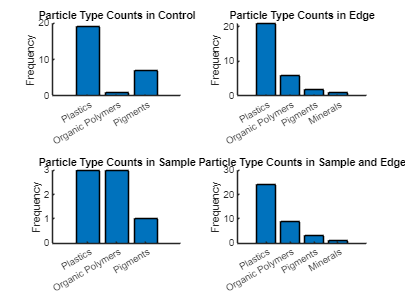

% combined into a 2x2 figure

cat_data = data(:, [1,3,4,5]); % data excluding the non-plastic column
tiledlayout(2,2)

nexttile(1)
%control
bar_cat = bar(cat_data(1,[1 2 3])); % excludes mineral category
xticklabels({'Plastics','Organic Polymers','Pigments'});
title('Particle Type Counts in Control');
ylabel('Frequency');
box off;

nexttile(2)
%edge
bar_cat = bar(cat_data(2,:));
xticklabels({'Plastics','Organic Polymers','Pigments','Minerals'});
title('Particle Type Counts in Edge');
ylabel('Frequency');
box off;

nexttile(3)
%sample
bar_cat = bar(cat_data(3,[1 2 3])); % excludes mineral category
xticklabels({'Plastics','Organic Polymers','Pigments'});
title('Particle Type Counts in Sample');
ylabel('Frequency');
box off;

nexttile(4)
%sample and edge
bar_cat = bar([24 9 3 1]);
xticklabels({'Plastics','Organic Polymers','Pigments','Minerals'});
title('Particle Type Counts in Sample and Edge');
ylabel('Frequency');
box off;

## Creates the palette and pie charts


% creates colors for each palstic types (13 types total)
palette_13color = [0,114,189;217,83,25;237,177,32;126,47,142;119,172,48;77,190,238;162,20,47;255,214,10;101,130,253;255,69,58;0,163,163;203,132,93;125,169,255];
palette_13color = palette_13color/255,

palette_13color =          0    0.4471    0.7412
    0.8510    0.3255    0.0980
    0.9294    0.6941    0.1255
    0.4941    0.1843    0.5569
    0.4667    0.6745    0.1882
    0.3020    0.7451    0.9333
    0.6353    0.0784    0.1843
    1.0000    0.8392    0.0392
    0.3961    0.5098    0.9922
    1.0000    0.2706    0.2275


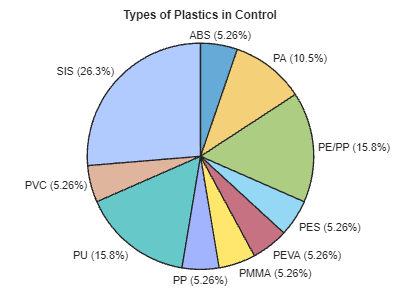


figure

% pie chart for control plastic types
control_plastics = [1 2 3 1 1 1 1 3 1 5];
control_labels = {'ABS', 'PA', 'PE/PP', 'PES', 'PEVA', 'PMMA', 'PP', 'PU', 'PVC', 'SIS' };

P1 = piechart(control_plastics, control_labels);
colororder(palette_13color([1 3 5 6 7 8 9 11 12 13],:));
title("Types of Plastics in Control");

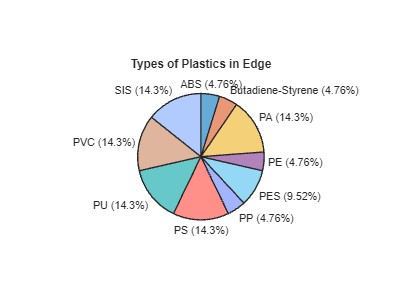



% pie chart for edge plastic types
edge_plastics = [1 1 3 1 2 1 3 3 3 3];
edge_labels = {'ABS', 'Butadiene-Styrene' 'PA', 'PE', 'PES', 'PP', 'PS', 'PU', 'PVC', 'SIS' };

P2 = piechart(edge_plastics, edge_labels);
colororder(palette_13color([1 2 3 4 6 9 10 11 12 13],:));
title("Types of Plastics in Edge");

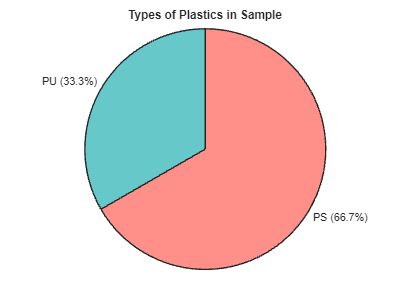



% pie chart for sample plastic types
sample_plastics = [2 1];
sample_labels = {'PS', 'PU'};

P3 = piechart(sample_plastics, sample_labels);
colororder(palette_13color([10 11],:));
title("Types of Plastics in Sample");

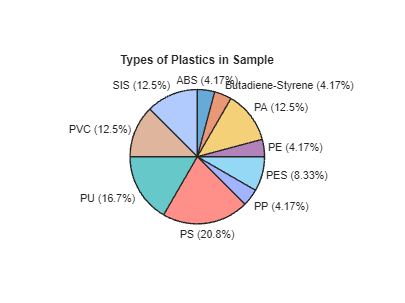



% pie chart for combined sample plastic types
total_sample_plastics = [1 1 3 1 2 1 5 4 3 3];
total_sample_labels = {'ABS', 'Butadiene-Styrene', 'PA', 'PE', 'PES', 'PP', 'PS', 'PU', 'PVC', 'SIS' };

P4 = piechart(total_sample_plastics, total_sample_labels);
colororder(palette_13color([1 2 3 4 6 9 10 11 12 13],:));
title("Types of Plastics in Sample");

## Code for determining color number from palette_13color

     1



         0    0.4471    0.7412



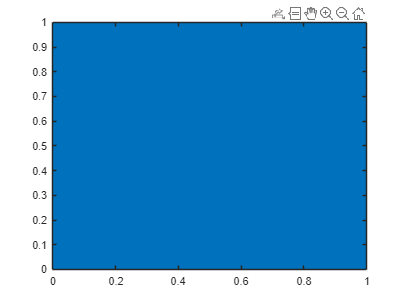

     5



    0.4667    0.6745    0.1882



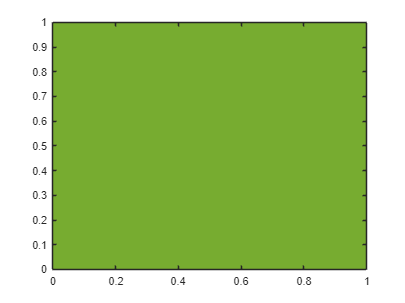

     7



    0.6353    0.0784    0.1843



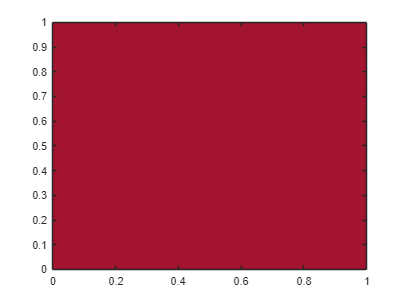

for k = [1, 5, 7]
    disp(k)
    disp(palette_13color(k,:))
    xc = [0 1 1 0];
    yc = [0 0 1 1];
    figure
    fill(xc, yc, palette_13color(k,:), 'EdgeColor', 'none')
end


% code for creating a legend for the plastics and colors
%plastics_labels = {'ABS', 'Butadiene-Styrene' 'PA', 'PE', 'PE/PP', 'PES', 'PEVA', 'PMMA', 'PP', 'PS', 'PU', 'PVC', 'SIS'};
%color_bar = bar([50,1,1,1,1,1,1,1,1,1,1,1,1;1,1,1,1,1,1,1,1,1,1,1,1,50])
%legend(plastics_labels)
%color_bar.FaceColor = 'flat';
%for k = 1:13
%color_bar.CData(k,:) = palette_13color(k,:);
%end


## Distribution plot

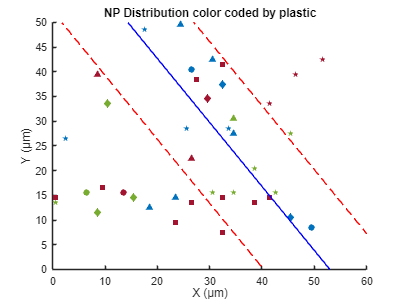

% ============================
% Importing the data (only the highlighed part in sheet 1, 
% fix the name as needed and put them in the same folder of code file)
% ============================
NPData = readtable('NP BAL data coords (2).xlsx', ...
                   'Sheet', 'Sheet1', ...
                   'Range', 'A18:D58');

% Extract coordinate data X and Y (columns C and D)
NPcoords = NPData{:, 3:4};  

% Extract plastic ID (column B)
plastic_id = NPData{:, 2};  

% ============================
% Plotting
% ============================
figure
hold on

unique_ids = unique(plastic_id);

for i = 1:length(unique_ids)
    pid = unique_ids(i);
    props = get_plot_properties(pid, palette_13color);
    
    idx = (plastic_id == pid);
    plot(NPcoords(idx,1), NPcoords(idx,2), ...
         "Marker", props.Marker, ...
         "MarkerFaceColor", props.Color, ...
         "MarkerEdgeColor", "none", ...
         "LineStyle", "none");
end

title("NP Distribution color coded by plastic");
ylabel("Y (μm)");
xlabel("X (μm)");
xlim([0,60])
ylim([0,50])

% ============================
% Draw main and tolerance lines
% ============================
s = 10;
m = -22/17;
b = 2331/34;
x = linspace(-10,62,10);
y1 = m*x + b;
y_hi = m*x + b + s*sqrt(1 + m^2);
y_lo = m*x + b - s*sqrt(1 + m^2);

plot(x, y1, "Color", "b");
plot(x, y_hi, "Color", "r", "LineStyle", "--");
plot(x, y_lo, "Color", "r", "LineStyle", "--");

hold off


% ============================
% Function: get_plot_properties
% ============================
function props = get_plot_properties(plastic_id, palette)
    % Maps plastic ID to marker shape and color using palette_13color

    switch plastic_id
        case {1, 2, 3}
            marker = "^";
            color = palette([7, 5, 1], :);
            idx = plastic_id;
            props = struct("Marker", marker, ...
                           "Color", color(idx, :), ...
                           "Label", "Group 1");
        case {7, 8, 9}
            marker = "o";
            color = palette([7, 5, 1], :);
            idx = plastic_id - 6;
            props = struct("Marker", marker, ...
                           "Color", color(idx, :), ...
                           "Label", "Group 2");
        case {4, 5, 6}
            marker = "diamond";
            color = palette([7, 5, 1], :);
            idx = plastic_id - 3;
            props = struct("Marker", marker, ...
                           "Color", color(idx, :), ...
                           "Label", "Group 3");
        case {10, 11, 12}
            marker = "pentagram";
            color = palette([7, 5, 1], :);
            idx = plastic_id - 9;
            props = struct("Marker", marker, ...
                           "Color", color(idx, :), ...
                           "Label", "Group 4");
        case 13
            marker = "square";
            props = struct("Marker", marker, ...
                           "Color", palette(7, :), ...
                           "Label", "Group 5");
        otherwise
            marker = "x";
            props = struct("Marker", marker, ...
                           "Color", [0 0 0], ...
                           "Label", "Unknown");
    end
end